# TALLER FINAL TAC

Julian Augusto Cortes Gomez -1803147

David Esteban Garcia Veloza - 1803346

clc
clear all
close all
format 

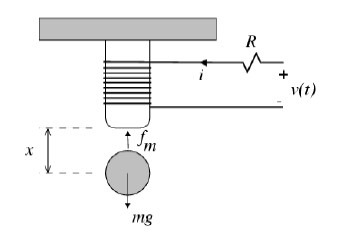

De manera inicial se procede a hallar las ecuaciones matematicas que describen el sistema mostrado anteriormente:


syms x2 x1 x3 L c m r g u

x1p=x2

$$x1p = x_{2}$$

x2p=g-(c/m)*((x3^2)/x1)

$$x2p = g-\frac{c\,{x_{3}}^{2}}{m\,x_{1}}$$

x3p=-(r/L)*x3+(1/L)*u

$$x3p = \frac{u}{L}-\frac{r\,x_{3}}{L}$$



xe=[x1,x2,x3]

$$xe = \left(\begin{array}{ccc} x_{1} & x_{2} & x_{3} \end{array}\right)$$

y=x1

$$y = x_{1}$$


A=jacobian([x1p,x2p,x3p],xe)

$$A = \left(\begin{array}{ccc} 0 & 1 & 0\\ \frac{c\,{x_{3}}^{2}}{m\,{x_{1}}^{2}} & 0 & -\frac{2\,c\,x_{3}}{m\,x_{1}}\\ 0 & 0 & -\frac{r}{L} \end{array}\right)$$

B=jacobian([x1p,x2p,x3p],u)

$$B = \left(\begin{array}{c} 0\\ 0\\ \frac{1}{L} \end{array}\right)$$

C=jacobian(y,xe)

$$C = \left(\begin{array}{ccc} 1 & 0 & 0 \end{array}\right)$$

D=jacobian(y,u)

$$D = 0$$

Vemos como las matrices del espacio de estados aun dependen de el punto de operacion y las constantes:


%%%%%%% constantes:

c=0.1

c = 0.1000

m=0.01

m = 0.0100

L=100e-3

L = 0.1000

r=10

r = 10

g=9.81

g = 9.8100


%%%%%%%% Ptos operacion
x1

$$x1 = x_{1}$$

x2=0

x2 = 0

x3=sqrt((m*g*x1)/c)

$$x3 = \sqrt{0.9810\,x_{1}}$$

u=r*x3

$$u = 10\,\sqrt{0.9810\,x_{1}}$$

Dejando como simbolico x1, tenemos el siguiente espacio de estados, el cual sera el usado para realizar los sistemas dinamicos.

%%%%%%%%%
A=eval(A)

$$A = \left(\begin{array}{ccc} 0 & 1 & 0\\ \frac{9.8100}{x_{1}} & 0 & -\frac{20\,\sqrt{0.9810\,x_{1}}}{x_{1}}\\ 0 & 0 & -100 \end{array}\right)$$

B=eval(B)

B =      0
     0
    10


C=eval(C)

C =      1     0     0


D=eval(D)

D = 0

%%%%%%%%%%%

Para hallar los sistemas constantes, usamos un valor de x1=7mm y se porcede a realizar los demas controles.

x1=7e-3

x1 = 0.0070

A=double(eval(A))

A = 	1.0e+03 *

         0    0.0010         0
    1.4014         0   -0.2368
         0         0   -0.1000


B

B =      0
     0
    10


C

C =      1     0     0


D

D = 0


[num,den]=ss2tf(A,B,C,D)

num = 	1.0e+03 *

         0         0         0   -2.3676


den = 	1.0e+05 *

    0.0000    0.0010   -0.0140   -1.4014


ft=tf(num,den)


ft =
 
                -2368
  ---------------------------------
  s^3 + 100 s^2 - 1401 s - 1.401e05
 
Continuous-time transfer function.



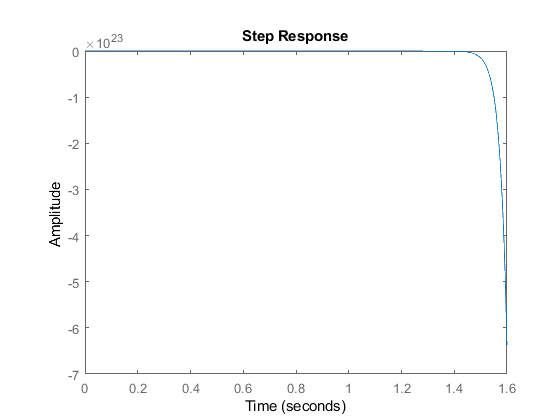

step(ft)


ts=0.5%s

ts = 0.5000

zeta=0.7

zeta = 0.7000

wn=4/(zeta*ts)

wn = 11.4286

syms x1

#### ***REGULADOR CTE's***

pd=[1 2*zeta*wn wn^2]

pd =     1.0000   16.0000  130.6122


pd=conv(pd,[1 5*zeta*wn])

pd = 	1.0e+03 *

    0.0010    0.0560    0.7706    5.2245


%%%% regulador
Kreg=retroIgualacion(A,B,pd)

Kreg = struct with fields:
    k1: [1×1 sym]
    k2: [1×1 sym]
    k3: [1×1 sym]


Kregulador=[double(Kreg.k1),double(Kreg.k2),double(Kreg.k3)]

Kregulador =   -35.3536   -0.9174   -4.4000


#### *REGULADOR DINAMICO*

Las ecuaciones de las constantes en funcion de x1 son:

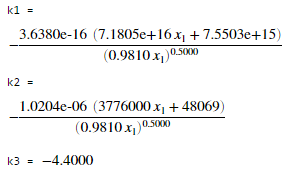

#### *SERVOSISTEMA CTE's*

pd=conv(pd,[1 5*zeta*wn])

pd = 	1.0e+05 *

    0.0000    0.0010    0.0301    0.3605    2.0898


Aempaq=[A,zeros(3,1);-C,0]

Aempaq = 	1.0e+03 *

         0    0.0010         0         0
    1.4014         0   -0.2368         0
         0         0   -0.1000         0
   -0.0010         0         0         0


Bempaq=[B;0]

Bempaq =      0
     0
    10
     0


KservoCTE=ackerMelo(Aempaq,Bempaq,pd)

KservoCTE =   -72.0490   -1.8635   -0.4000   88.2650



pd=[1 2*zeta*wn wn^2]

pd =     1.0000   16.0000  130.6122


pd=conv(pd,[1 5*zeta*wn])

pd = 	1.0e+03 *

    0.0010    0.0560    0.7706    5.2245



%Observador
tso=ts/10

tso = 0.0500

wno=4/(zeta*tso)

wno = 114.2857

pdo=[1 2*zeta*wno wno^2]

pdo = 	1.0e+04 *

    0.0001    0.0160    1.3061


pdo=conv(pdo,[1 5*zeta*wno])

pdo = 	1.0e+06 *

    0.0000    0.0006    0.0771    5.2245


Kl=ObsIgual(A,C,zeta,tso);
kl1=double(Kl.k1);
kl2=double(Kl.k2);
kl3=double(Kl.k3);
Kl=[kl1;kl2;kl3]

Kl =         2700
     1657900
    -2058600


#### SERVOSISTEMA DINAMICO

Las ecuaciones de Ke en funcion de x1 son:

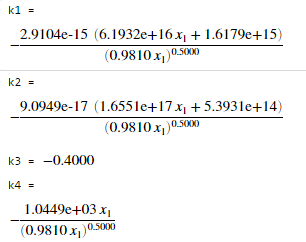

Y las del observador en funcion de x1:

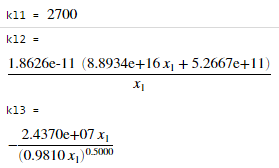

#### *SERVOSISTEMA DISCRETO CTE's*

[AB,BB,CB]=Canonics(A,B,C,D)

AB = 	1.0e+05 *

         0    0.0000         0
         0         0    0.0000
    1.4014    0.0140   -0.0010


BB =      0
     0
     1


CB = 	1.0e+03 *

   -2.3676         0         0


DB=0

DB = 0


ed=0.7;
tsd=0.5;%s
wnd=4/(ed*tsd);
tm=tsd/10

tm = 0.0500


syms s t T
I=eye(3);
Gt=ilaplace(vpa((s*I-AB)^-1));
GT=subs(Gt,t,T);
T=tm

T = 0.0500

Hallamos las matrices G y H del sistema

GZ=eval(GT)

GZ = 	1.0e+03 *

    0.0025    0.0001    0.0000
    0.0840    0.0033    0.0000
    3.4753    0.1188    0.0008



HTs=int(Gt,t,0,T)*BB;
HZ=eval(HTs)

HZ =     0.0000
    0.0006
    0.0248


Diseñamos el polinomio deseado en discreto.

p1=-2*exp(-ed*wnd*tm)*cos(wnd*tm*sqrt(1-ed^2));
p2=exp(-2*ed*wnd*tm);
pd=conv([1 p1 p2],[1 -0.05])

pd =     1.0000   -1.2806    0.5109   -0.0225


pd=conv(pd,[1 -0.05])

pd =     1.0000   -1.3306    0.5749   -0.0480    0.0011


Hallamos el G gorro y H gorro y se hallan las constantes

AE=[GZ zeros(3,1);CB*GZ 1]

AE = 	1.0e+03 *

    0.0025    0.0001    0.0000         0
    0.0840    0.0033    0.0000         0
    3.4753    0.1188    0.0008         0
   -5.8872   -0.2013   -0.0014    0.0010


BE=[HZ;CB*HZ]

BE =     0.0000
    0.0006
    0.0248
   -0.0251


S=[BE AE*BE AE^2*BE AE^3*BE]

S =     0.0000    0.0001    0.0006    0.0039
    0.0006    0.0035    0.0225    0.1465
    0.0248    0.1291    0.8450    5.4930
   -0.0251   -0.2435   -1.6734  -10.9684


phia=pd(1)*AE^4+pd(2)*AE^3+pd(3)*AE^2+pd(4)*AE+eye(4)*pd(5)

phia = 	1.0e+06 *

    0.0005    0.0000    0.0000         0
    0.0196    0.0007    0.0000         0
    0.7358    0.0270    0.0002         0
   -1.4713   -0.0541   -0.0004    0.0000


KESCALON=[0 0 0 1]*(inv(S))*phia;
KI=KESCALON(4)

KI = -2.5292

KESCALON=[KESCALON(1) KESCALON(2) KESCALON(3)]

KESCALON = 	1.0e+05 *

    1.6005    0.0587    0.0004


%Observador

Se halla el observador de estados:

LO=GZ^2*([CB;CB*GZ;CB*GZ^2])^-1*[0;0;1]

LO =    -0.0004
   -0.0166
   -0.5904


# Resultados

## Reguladores

De manera inicial, se realizan reguladores, uno con constantes y otro con variables, si vemos el primer montaje es asi:

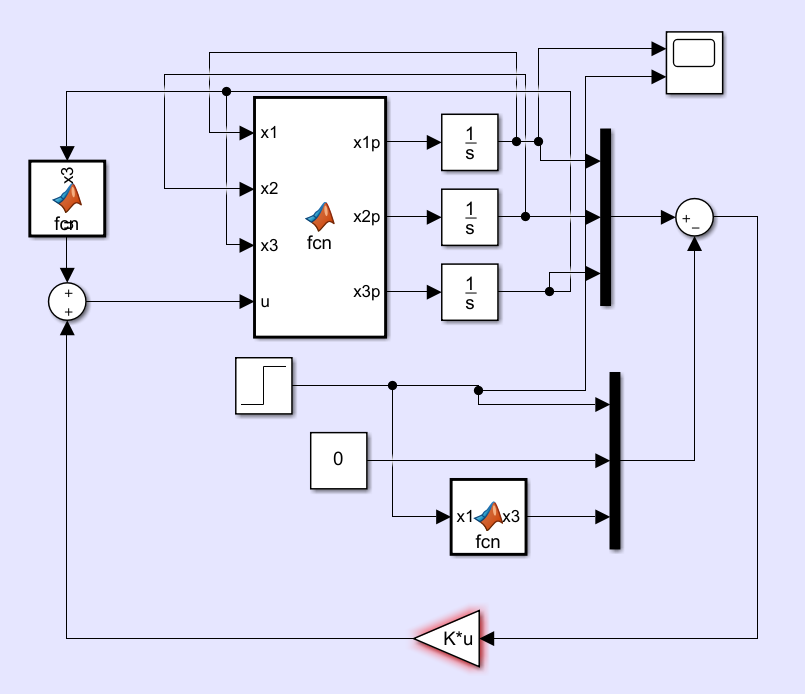

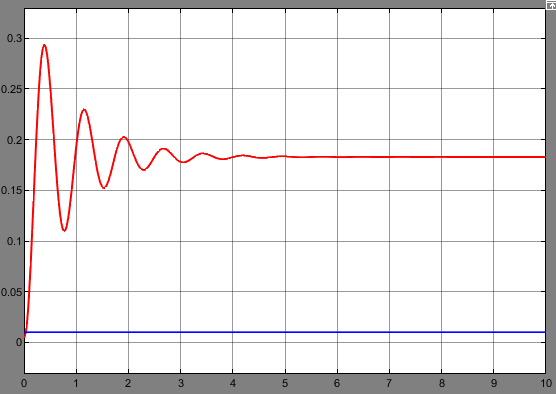

Y si lo hacemos con las funciones variables:

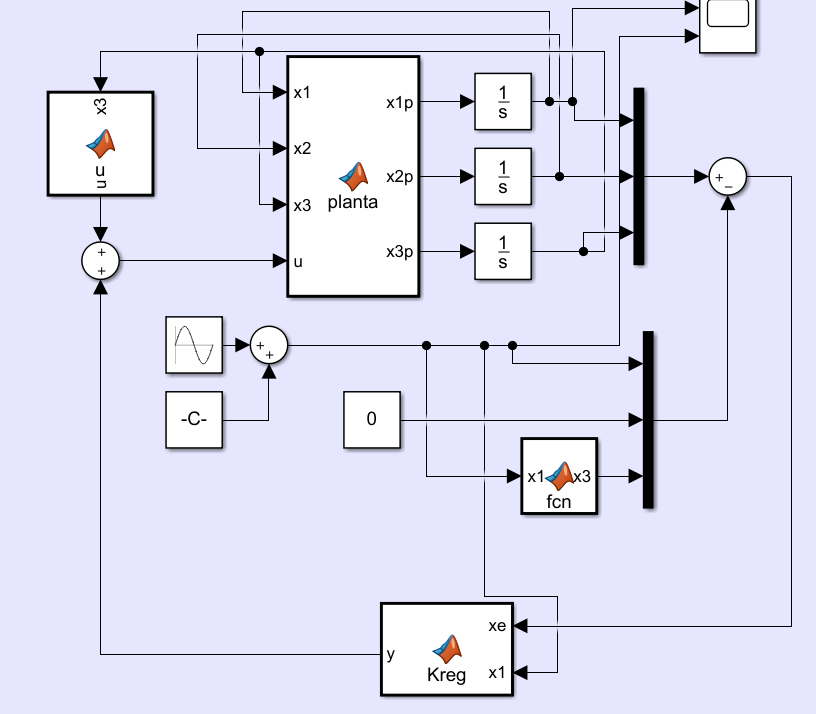

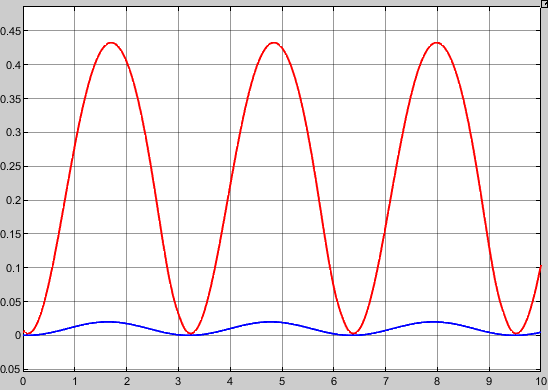

#### MONTAJE NUMERO 1: SERVOSISTEMA CON CONSTANTES

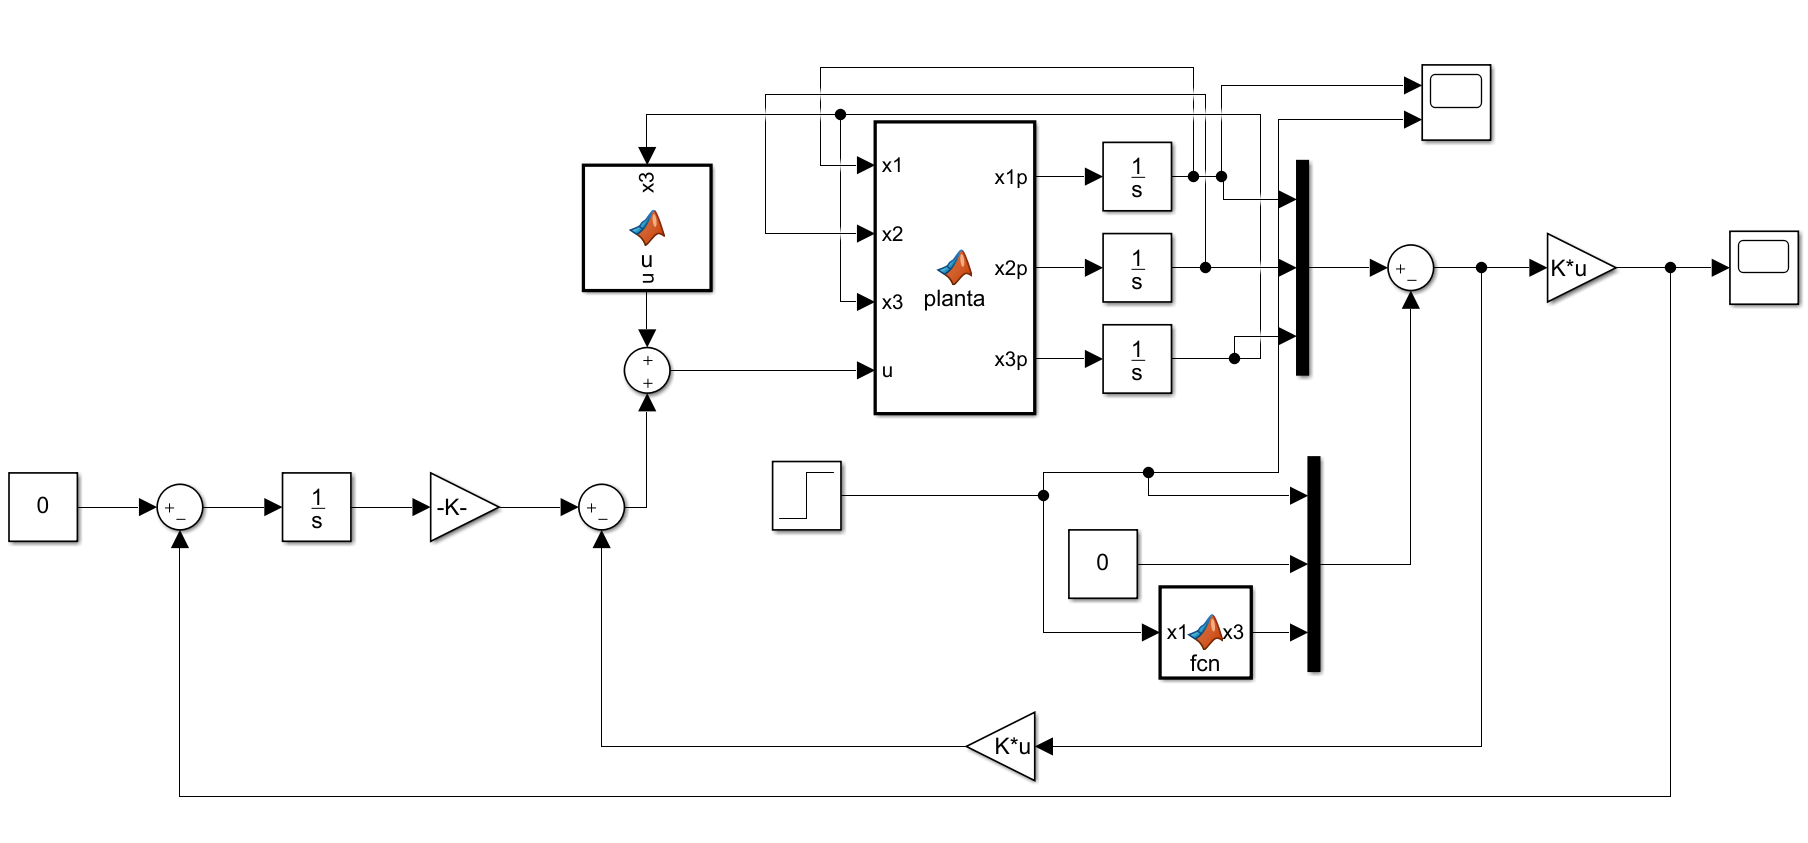

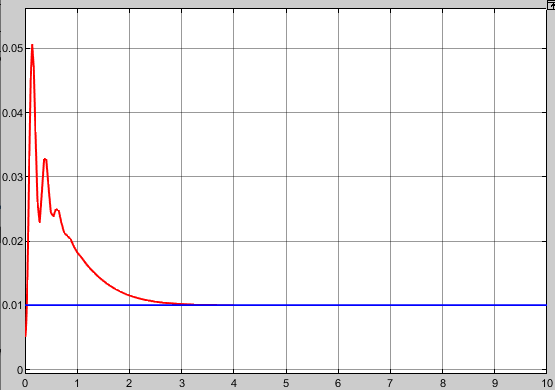

Donde vemos que sigue la referencia de 10mm

#### MONTAJE NUMERO 2: SERVOSISTEMA CON OBSERVADOR

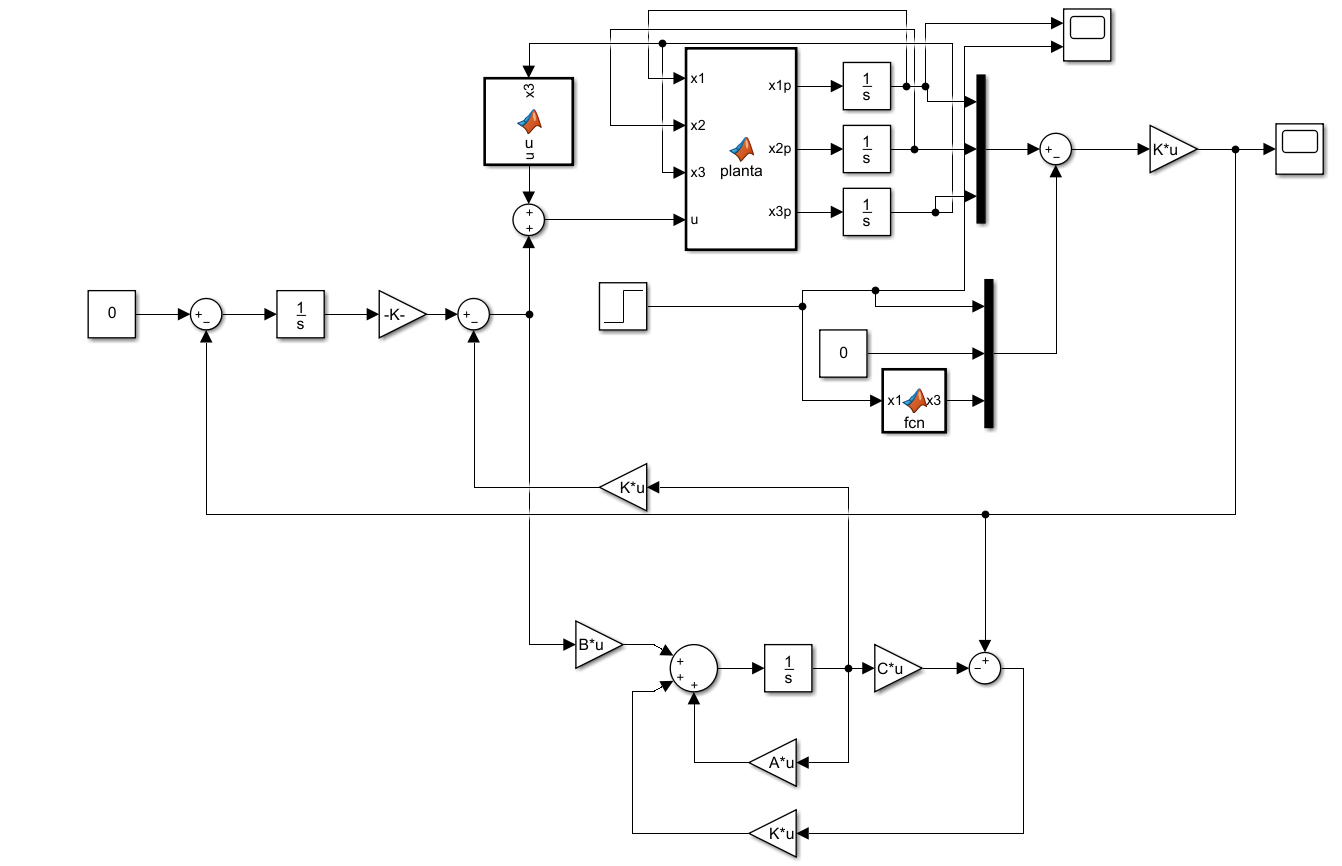

#### MONTAJE NUMERO 3: SERVOSISTEMA DINAMICO 

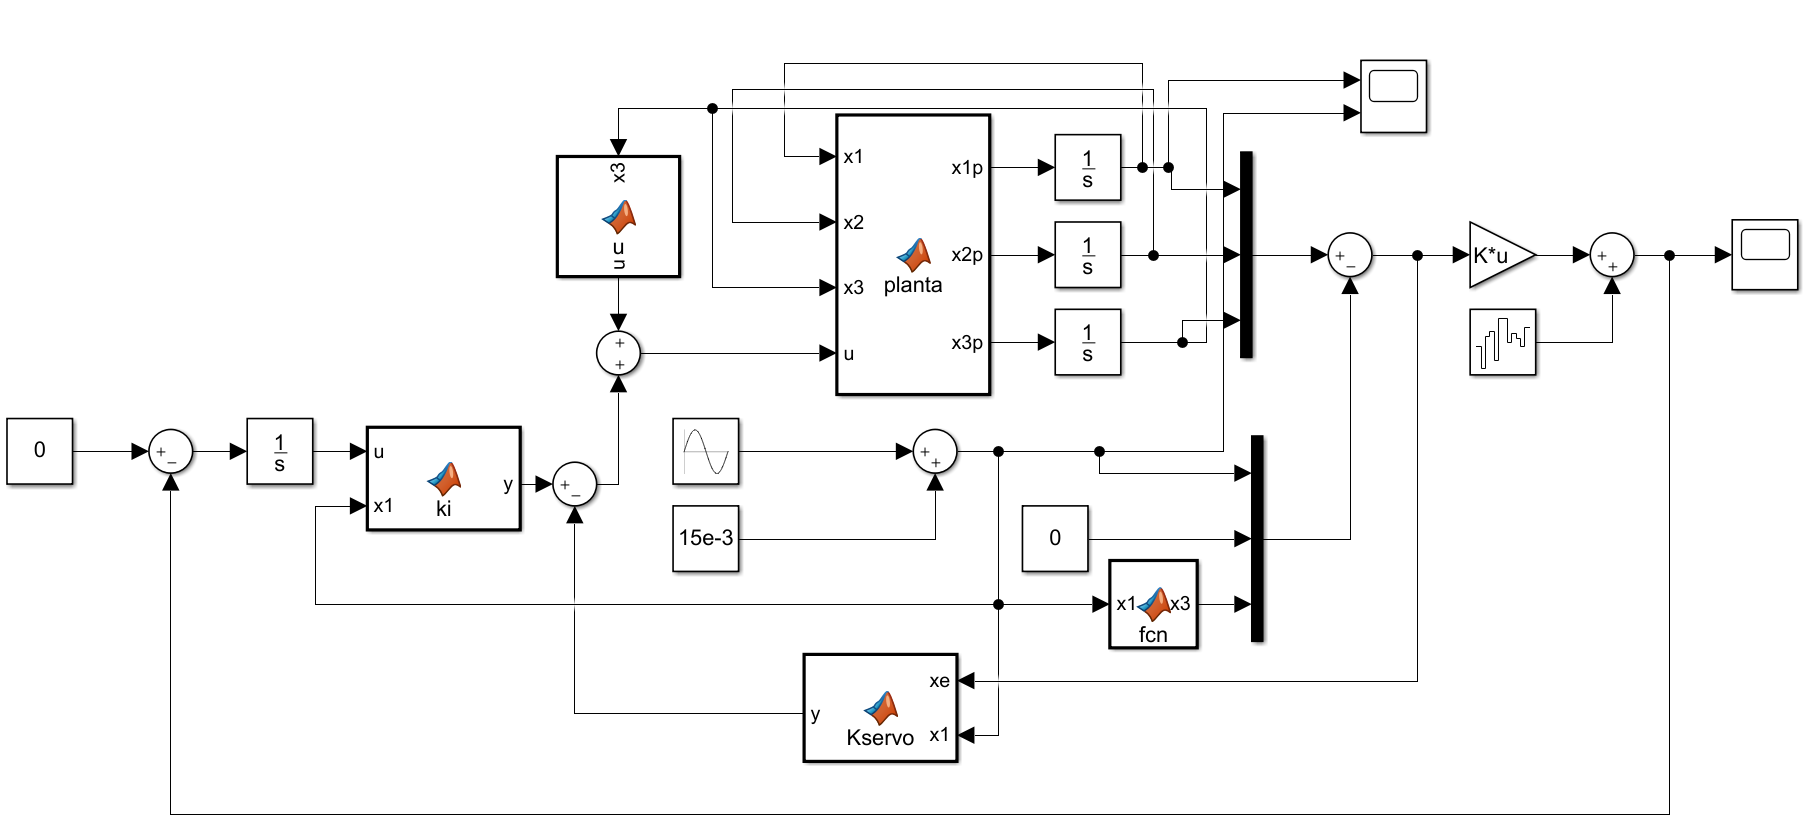

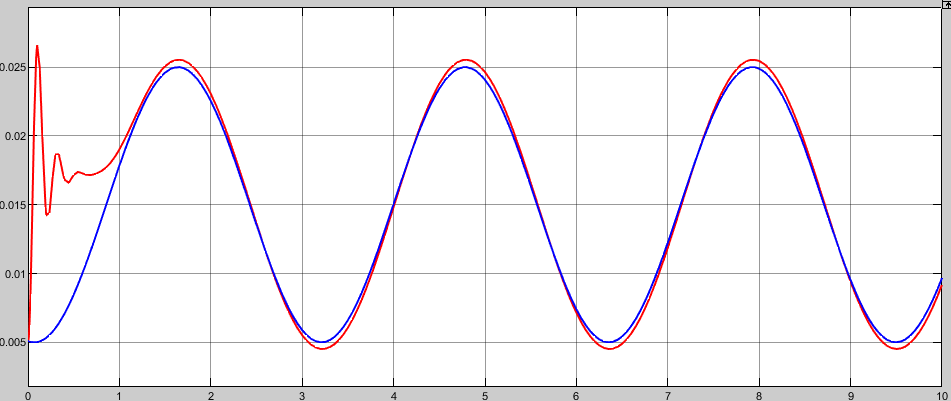

Donde vemos la salida sigue la señal senoidal con un error muy bajo, si miramos la salida del sistema veremos como sigue el cero:

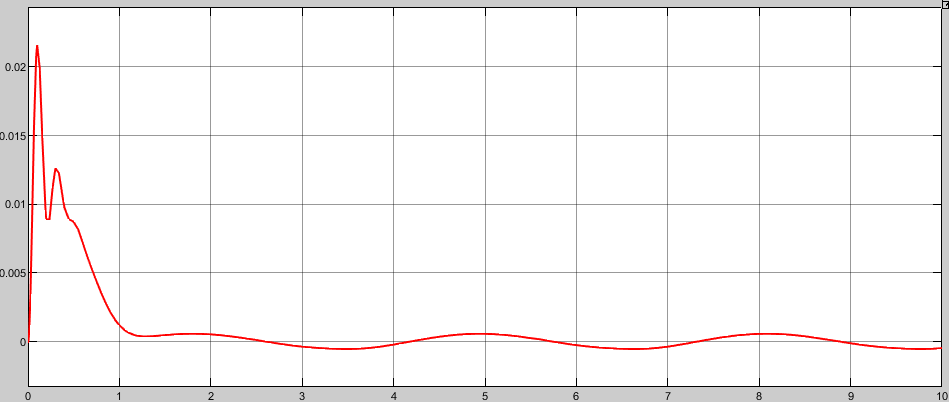

Si ahora vemos el comportamiento con white noise con power de 1e-7, tenemos:

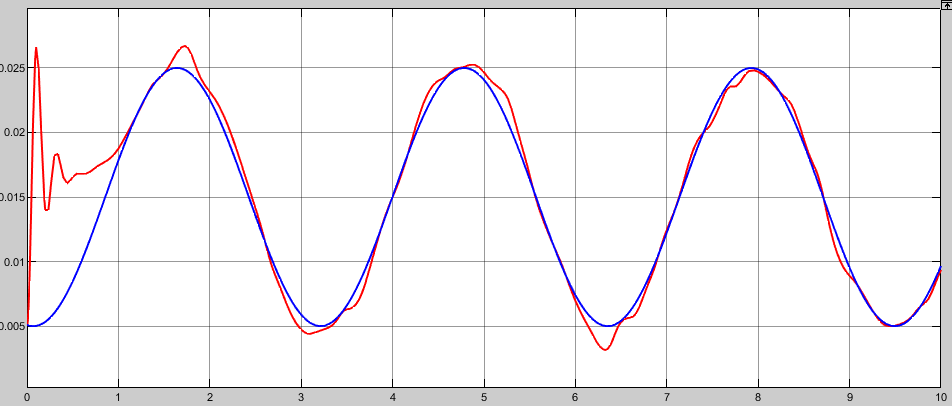

#### MONTAJE NUMERO 4: SERVOSISTEMA DINAMICO CON OBSERVADOR

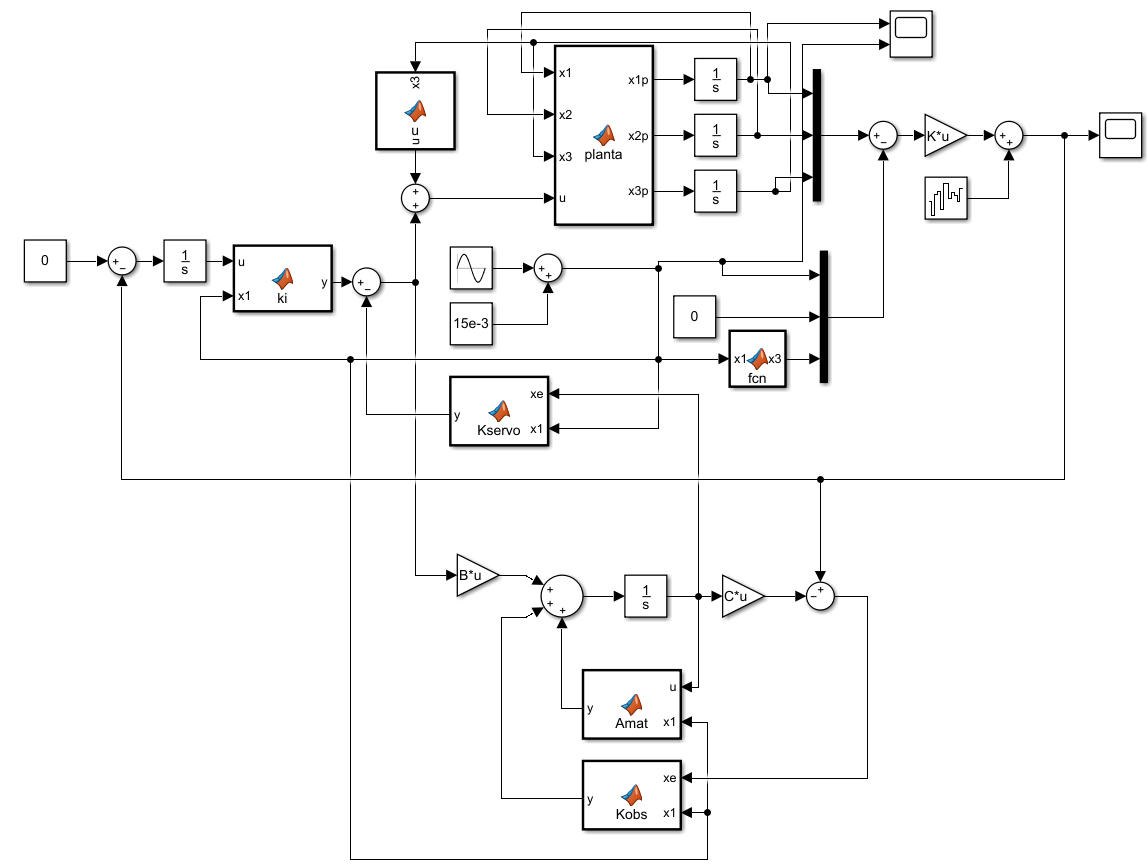

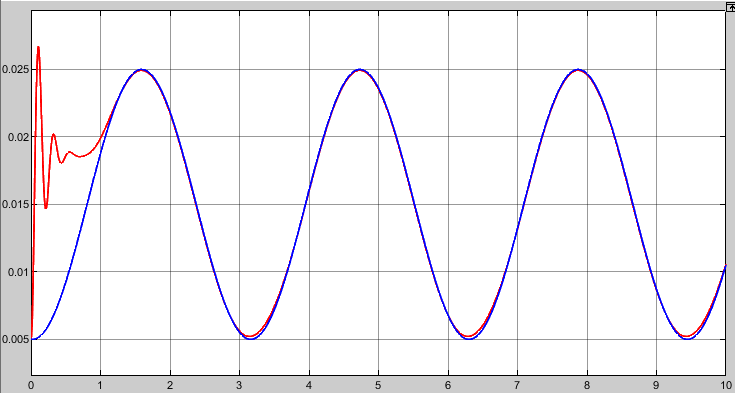

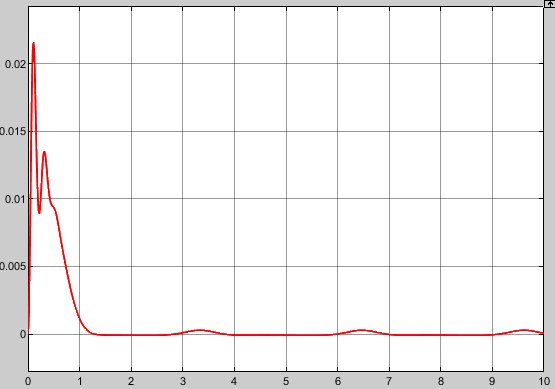

Si ahora añdimos ruido blanco, vemos el siguiente comportamiento con un noise power de 1e-8:

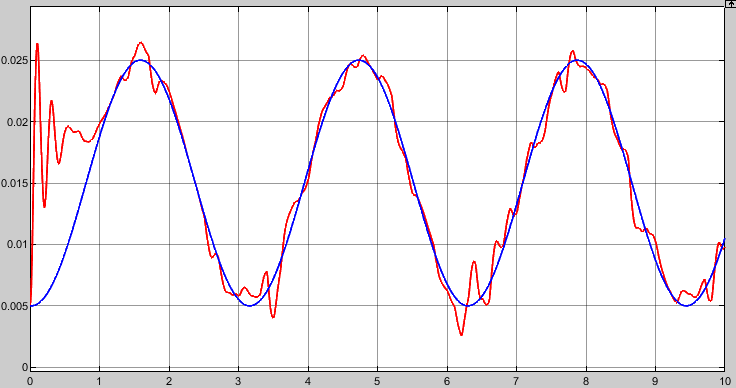

Aunque el sistema se mantiene siguiendo la señal, el ruido es notorio, mucho mas que el sistema sin observador, y aun siendo mucho menor el ruido de este.

#### MONTAJE 5: SERVOSISTEMA DISCRETO CON OBSERVADOR

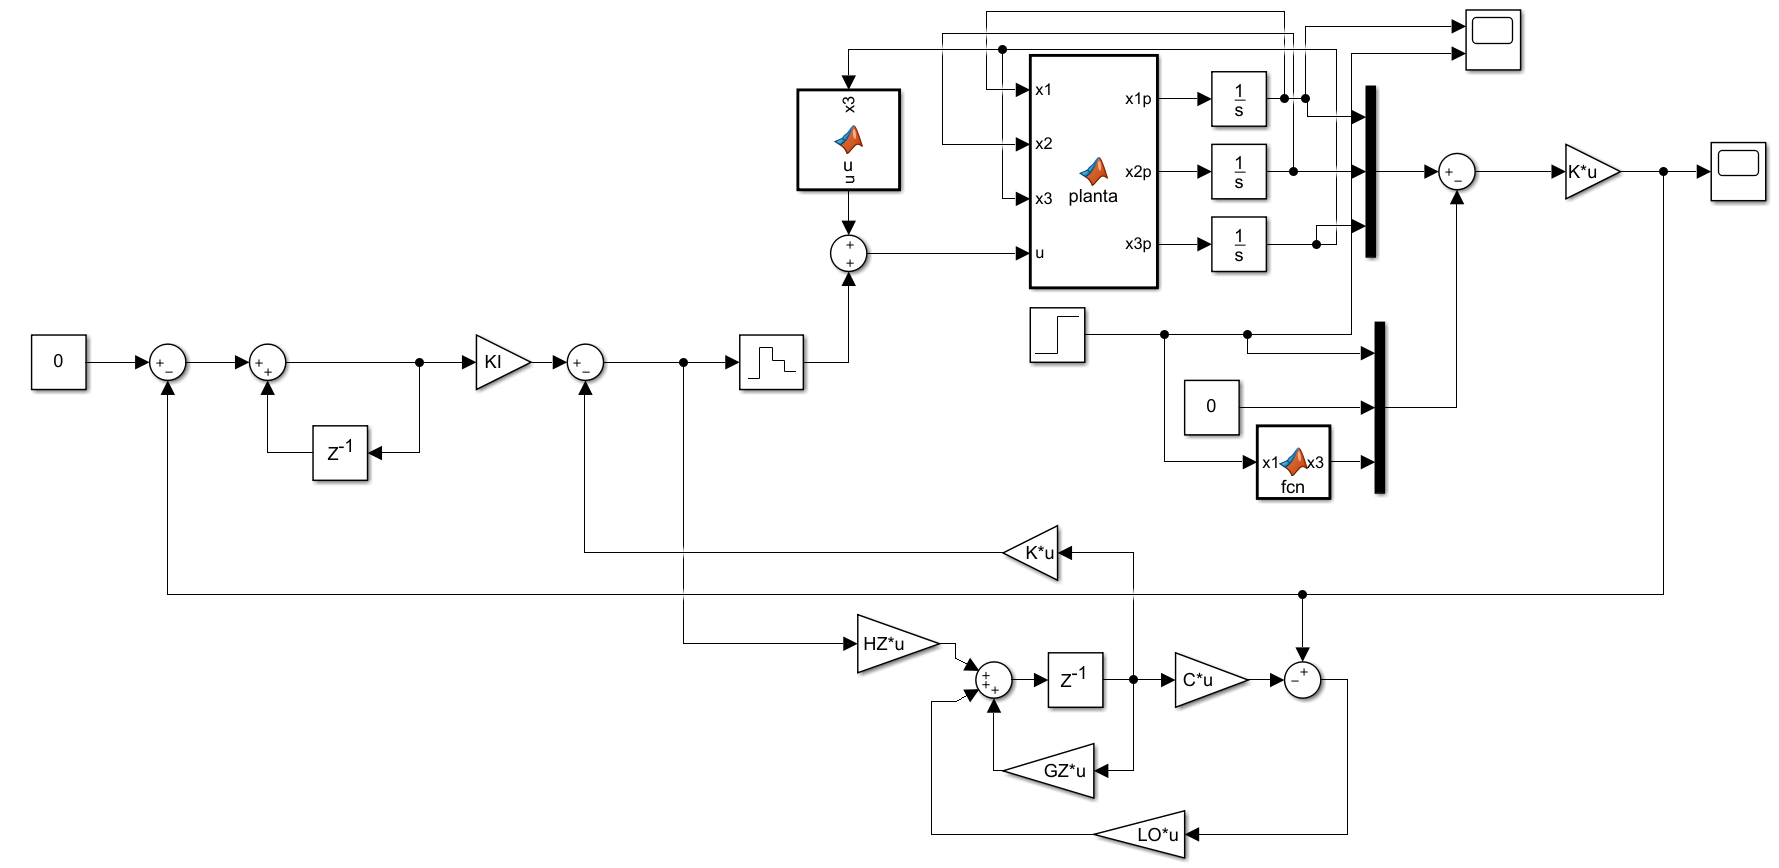

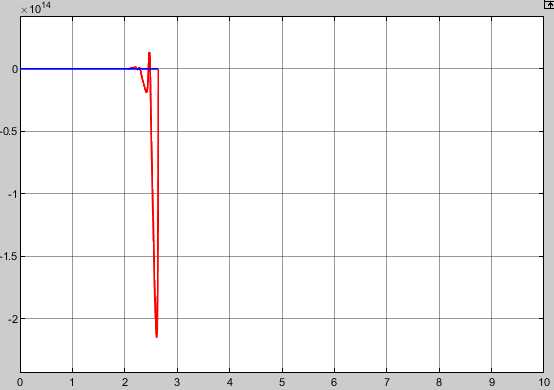

#### MONTAJE 6: SERVOSISTEMA DINAMICO DISCRETO CON OBS

#### ***CONCLUSIONES:***

- El uso de observador de estados hace mas facil su umplementacion real, al solo tener que sensar una salida, pero lo hace mucho mas suceptible al ruido que el sistema sin observador de estados como se vio en el caso de los servosistemas com white noise.

- El uso de sistemas de control dinamicos en plantas no lineales, hacen que sean mucho mas amplios en su aplicacion real, esto debido a que si rango de operacion varia justo en donde se le necesite controlar. lo que hace mas dificil su inestabilidad.